**Analysis on FNDDS 2009-2010**

it requires subplotplus

[https://www.mathworks.com/matlabcentral/fileexchange/34594-subplotplus-enhanced-layout-matlab-subplot-function](https://www.mathworks.com/matlabcentral/fileexchange/34594-subplotplus-enhanced-layout-matlab-subplot-function)

it requires cbrewer

[https://www.mathworks.com/matlabcentral/fileexchange/34087-cbrewer-colorbrewer-schemes-for-matlab](https://www.mathworks.com/matlabcentral/fileexchange/34087-cbrewer-colorbrewer-schemes-for-matlab)

Load data

load('fndds_analysis.mat')

Scaling relation between linear average and standard deviation

muf=zeros(size(fooddatabase0910selclean,1),1);
sf=zeros(size(fooddatabase0910selclean,1),1);


for ind=1:size(fooddatabase0910selclean,1)
    v=fooddatabase0910selclean(ind,:);
    muf(ind)=mean(v(v>0));
    sf(ind)=std(v(v>0));
end

cvreal=sf./muf;
tfndds.muf=muf;
tfndds.sf=sf;

x1=log(muf);
y1=log(sf);
ft = fittype( 'poly1' );
[fitresult, gof] = fit(x1, y1, ft );

disp(fitresult)

     Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9423  (0.9133, 0.9713)
       p2 =      0.5571  (0.376, 0.7382)


disp(gof)

           sse: 29.0239
       rsquare: 0.9772
           dfe: 97
    adjrsquare: 0.9770
          rmse: 0.5470



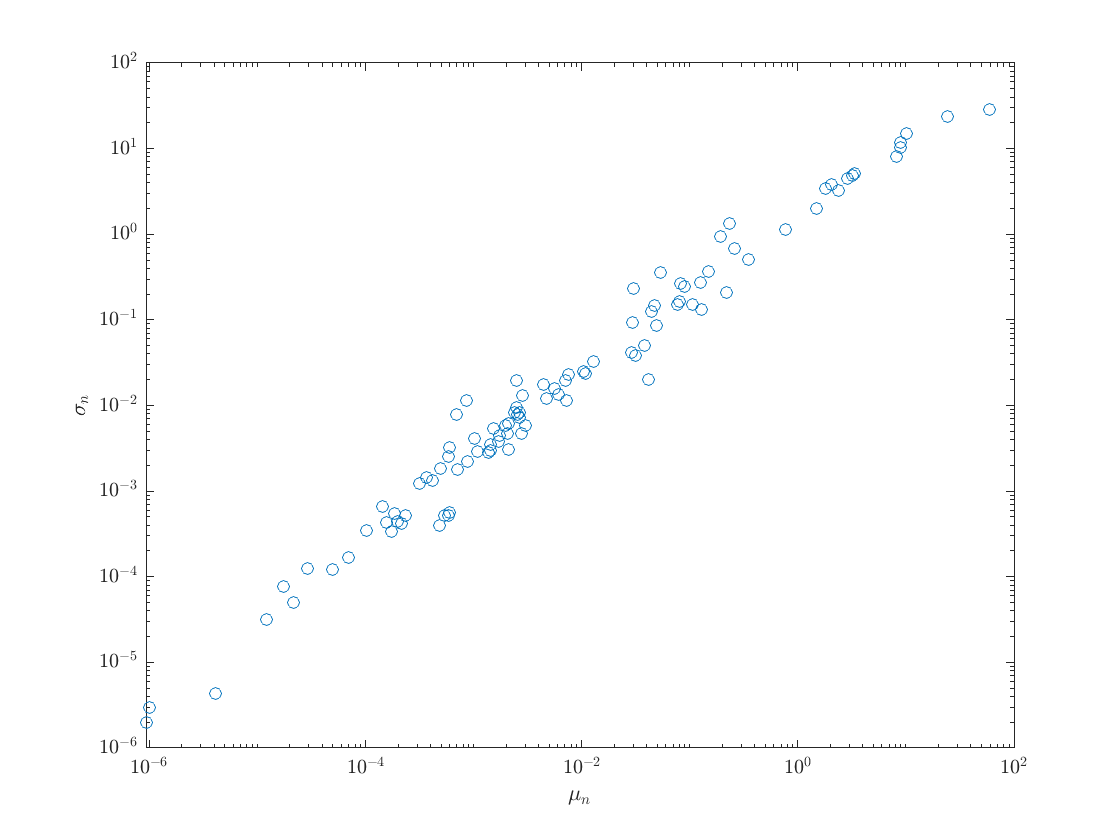



figure,
loglog(muf,sf, 'o')
xlabel('$\mu_n$','Interpreter', 'Latex')
ylabel('$\sigma_n$','Interpreter', 'Latex')


%%%%%%%%%%%%% remove water

label="Water";
mufn=muf;
sfn=sf;
mufn(strcmpi(label, tfndds.Nutrient_description))=[];
sfn(strcmpi(label, tfndds.Nutrient_description))=[];
lbl=tfndds.ischem;
lbl(strcmpi(label, tfndds.Nutrient_description))=[];
muf1n=mufn(lbl);
sf1n=sfn(lbl);

x1=log(mufn);
y1=log(sfn);
ft = fittype( 'poly1' );
[fitresult, gof] = fit( x1, y1, ft );

disp(fitresult)

     Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9496  (0.9202, 0.979)
       p2 =       0.605  (0.4207, 0.7893)


disp(gof)

           sse: 27.8286
       rsquare: 0.9771
           dfe: 96
    adjrsquare: 0.9769
          rmse: 0.5384



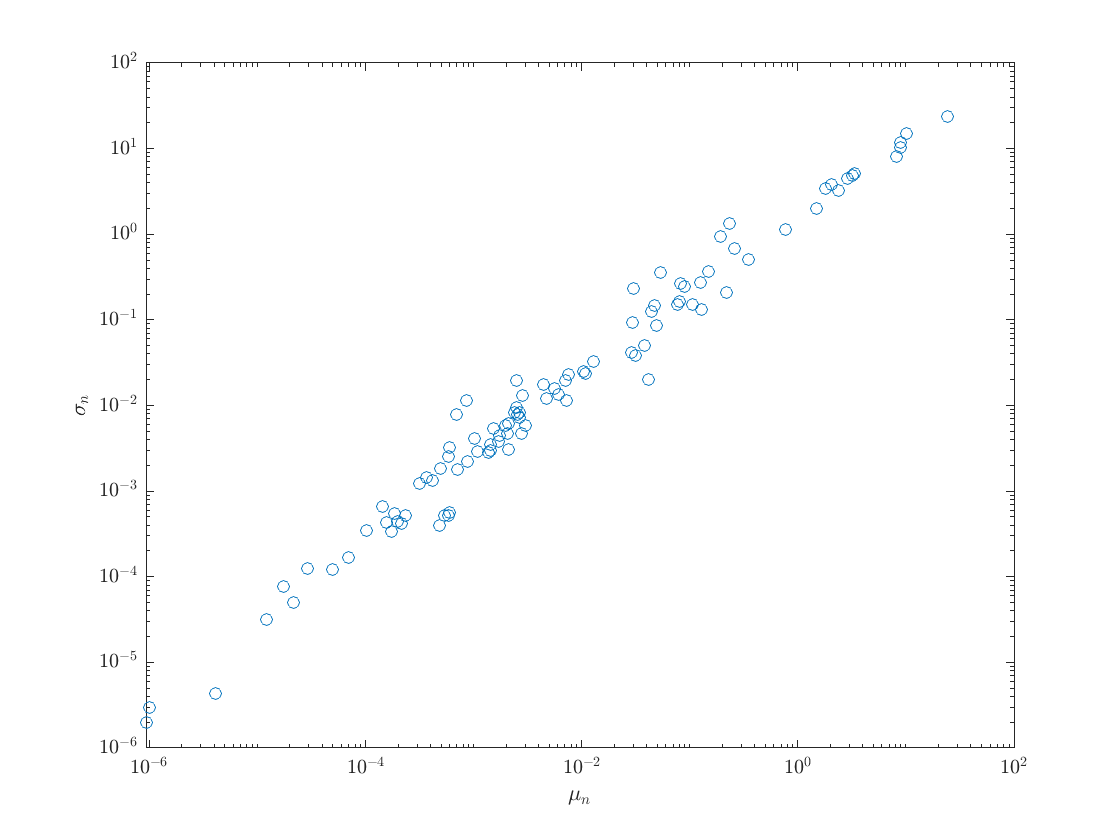



figure,
loglog(mufn,sfn, 'o')
xlabel('$\mu_n$','Interpreter', 'Latex')
ylabel('$\sigma_n$','Interpreter', 'Latex')

Fitting

nuttablestat=script_fit_nutrients(nutlist, fooddatabase0910selclean, muf,sf);

****************************************************************
     1

        4776

    8.1740    8.0398

****************************************************************
     2

        4730

    8.9792   11.6350

****************************************************************
     3

        4577

   24.2680   23.7582

****************************************************************
     4

    86

    8.8163   10.4322

****************************************************************
     5

        4880

   58.8591   28.2737

     5

Truncated Lognormal
No convergence
        4880



****************************************************************
     6

   380

    0.0300    0.2315

****************************************************************
     7

   315

    0.1071    0.1522

****************************************************************
     8

        4386

   10.0662   14.9508

****************************************************************
     9

        3857

    2.3964    3.2614

****************************************************************
    10

        4822

    0.0775    0.1509

****************************************************************
    11

        4817

    0.0021    0.0047

****************************************************************
    12

        4809

    0.0289    0.0421

****************************************************************
    13

        4807

    0.1292    0.1322

****************************************************************
    14

        4862

    0.2170    0.2102

*******************************

****************************************************************
    18

        4702

   1.0e-04 *

    0.1215    0.3177



    18

Truncated Gaussian
No convergence
Fit Half Gaussian
        4702

****************************************************************
    19

        2821

   1.0e-03 *

    0.1022    0.3490



****************************************************************
    20

        3434

    0.0004    0.0013



****************************************************************
    21

        1379

   1.0e-03 *

    0.1837    0.5410



****************************************************************
    22

        4638

    0.0011    0.0029

****************************************************************
    23

        2278

   1.0e-05 *

    0.0931    0.1985



****************************************************************
    24

        1381

   1.0e-03 *

    0.0292    0.1240



****************************************************************
    25

   713

    0.0021    0.0031

****************************************************************
    26

        3382

    0.0004    0.0014



****************************************************************
    27

        3351

    0.0104    0.0248

****************************************************************
    28

        4709

   1.0e-03 *

    0.1997    0.4401



****************************************************************
    29

        4760

   1.0e-03 *

    0.2147    0.4240



****************************************************************
    30

        4748

    0.0028    0.0048

****************************************************************
    31

        4692

   1.0e-03 *

    0.2326    0.5262



****************************************************************
    32

        4621

   1.0e-03 *

    0.0494    0.1224



****************************************************************
    33

        3306

   1.0e-05 *

    0.0995    0.2949



****************************************************************
    34

        4774

    0.0312    0.0380

****************************************************************
    35

        4379

   1.0e-04 *

    0.1741    0.7670



****************************************************************
    36

        1881

   1.0e-03 *

    0.0691    0.1676



****************************************************************
    37

        4554

   1.0e-04 *

    0.2159    0.4949



    37

Truncated Gaussian
No convergence
Fit Half Gaussian
        4554

****************************************************************
    38

   108

    0.0072    0.0115

****************************************************************
    39

   247

   1.0e-05 *

    0.4089    0.4322



****************************************************************
    40

        2765

    0.0491    0.0857

****************************************************************
    41

        4689

    2.8682    4.4329

****************************************************************
    42

        1693

    0.1268    0.2729

****************************************************************
    43

        1462

    0.0801    0.1619

****************************************************************
    44

        1853

    0.0828    0.2689

****************************************************************
    45

        2585

    0.0902    0.2474

****************************************************************
    46

        3234

    0.2326    1.3378

****************************************************************
    47

        4083

    0.2615    0.6789

****************************************************************
    48

        4675

    1.4862    1.9725

*******************

****************************************************************
    65

   128

    0.0014    0.0028

****************************************************************
    66

   592

    0.0028    0.0129

****************************************************************
    67

   157

    0.0018    0.0045

****************************************************************
    68

   254

    0.0026    0.0078

****************************************************************
    69

   142

    0.0061    0.0134

****************************************************************
    70

   266

    0.0015    0.0054

****************************************************************
    71

   295

    0.0025    0.0195

****************************************************************
    72

        1017

    0.0017    0.0038

****************************************************************
    73

   442

    0.0007    0.0018

****************************************************************
  

****************************************************************
    76

   243

    0.0020    0.0059

****************************************************************
    77

    24

   1.0e-03 *

    0.5396    0.5207

****************************************************************
    78

    24

    0.0416    0.0202

****************************************************************
    79

   190

    0.0005    0.0018



****************************************************************
    80

   218

    0.0030    0.0059

****************************************************************
    81

   436

    0.0010    0.0041

****************************************************************
    82

   602

    0.0009    0.0116



****************************************************************
    83

        1293

    0.0003    0.0012



****************************************************************
    84

   968

    0.0006    0.0026

****************************************************************
    85

        1787

    0.0006    0.0032



****************************************************************
    86

        1238

   1.0e-03 *

    0.1446    0.6629



****************************************************************
    87

        2532

    0.0014    0.0030

****************************************************************
    88

    24

   1.0e-03 *

    0.6029    0.5696

****************************************************************
    89

    19

   1.0e-03 *

    0.5863    0.5190

****************************************************************
    90

    23

   1.0e-03 *

    0.4804    0.3935



****************************************************************
    91

    94

   1.0e-03 *

    0.1750    0.3335



****************************************************************
    92

        2843

    0.0071    0.0198

****************************************************************
    93

   614

    0.0075    0.0232

****************************************************************
    94

        1104

    0.0047    0.0120

****************************************************************
    95

        1104

    0.0056    0.0158

****************************************************************
    96

   449

    0.0027    0.0072

****************************************************************
    97

        1341

    0.0007    0.0079



****************************************************************
    98

        2575

    0.0021    0.0061

    98

Truncated Gaussian
No convergence
Fit Half Gaussian
        2575

****************************************************************
    99

   440

    0.0044    0.0177



nuttablestat.ischem=tfndds.ischem;
nutlist.muL=nuttablestat.muL;
nutlist.sigmaL=nuttablestat.sigmaL;

Effect of Truncation

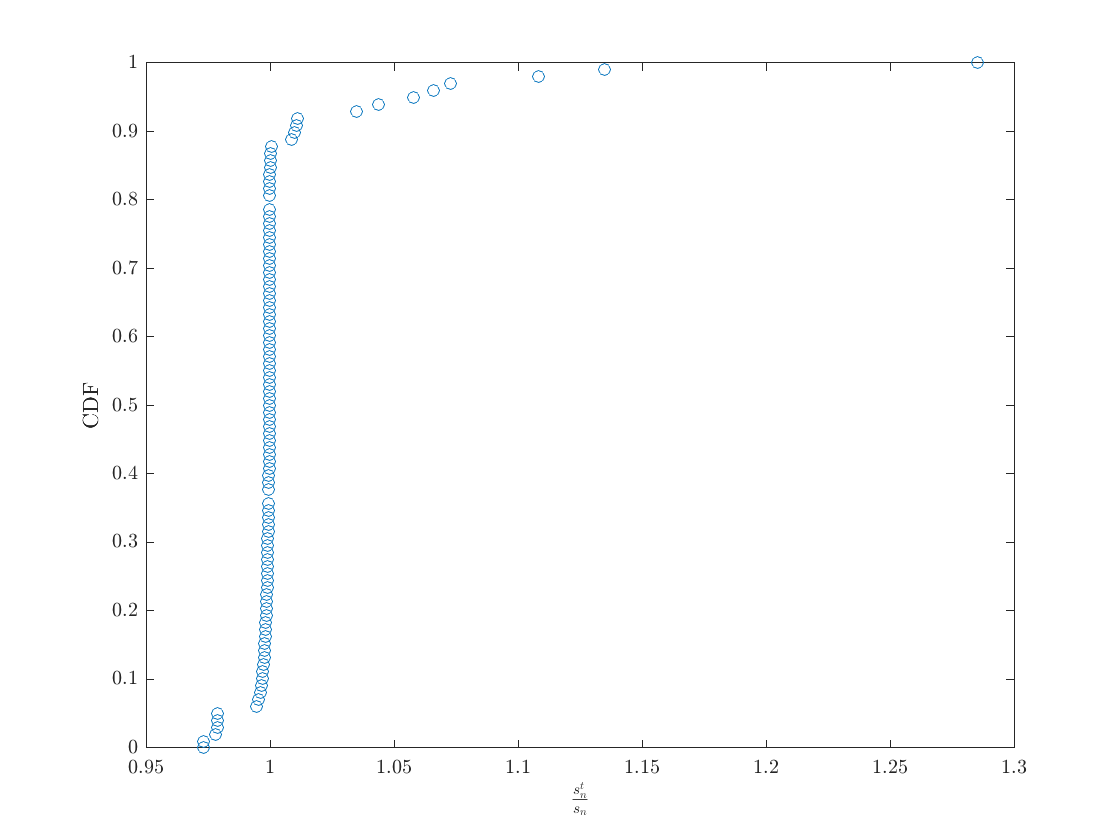

tfluc=table;
tfluc.Nutrient_description=nuttablestat.Nutrient_description;
tfluc.ratioS=nuttablestat.sigmaLt./nuttablestat.sigmaL;
tfluc.ratioM=nuttablestat.muLt./nuttablestat.muL;


figure,
[y,x]=ecdf(tfluc.ratioS);
plot(x,y, 'o')
xlabel('$\frac{s_n^t}{s_n}$','Interpreter', 'Latex')
ylabel('CDF')


ts=1.0115;
% Water does not converge
label="Water";
flagsel=or(strcmpi(label, nuttablestat.Nutrient_description), tfluc.ratioS>=ts);

mufn=muf;
sfn=sf;
mufn(flagsel)=[];
sfn(flagsel)=[];


x1=log(mufn);
y1=log(sfn);
ft = fittype( 'poly1' );
[fitresult, gof] = fit( x1, y1, ft );

disp(fitresult)

     Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9676  (0.9308, 1.004)
       p2 =      0.7301  (0.4907, 0.9696)


disp(gof)

           sse: 26.7913
       rsquare: 0.9688
           dfe: 88
    adjrsquare: 0.9684
          rmse: 0.5518



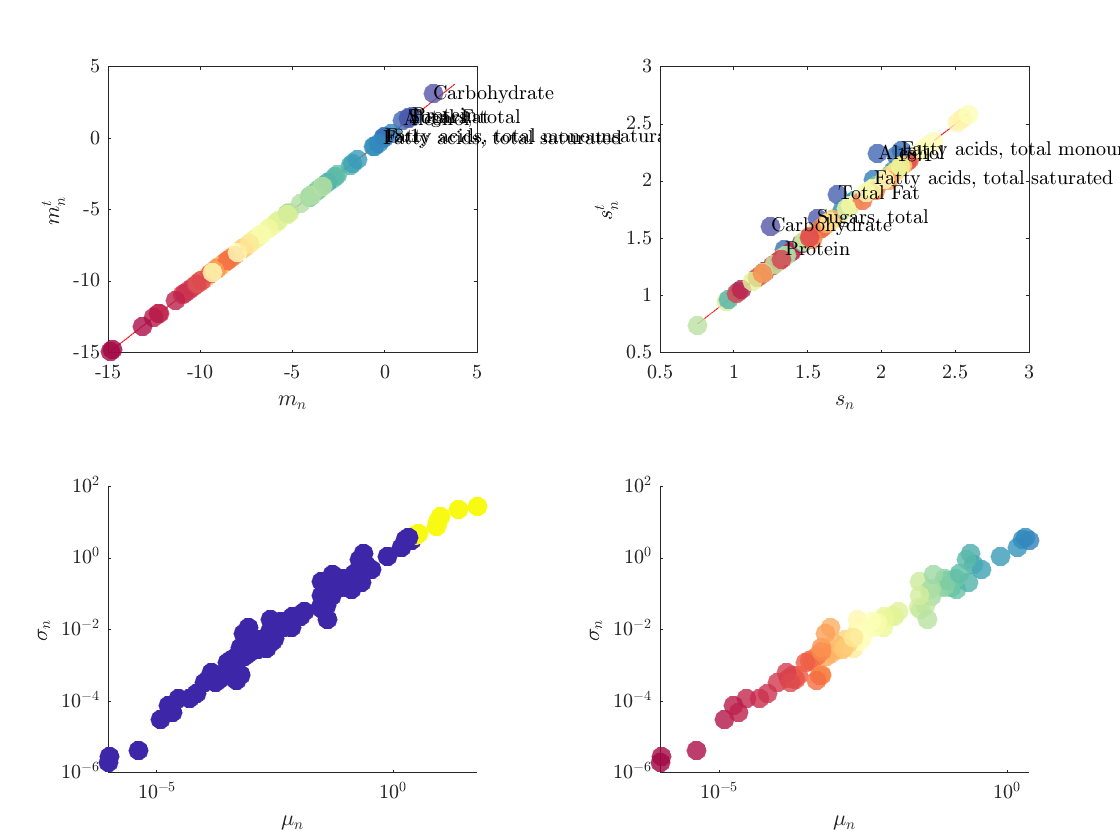



C = {{{[]}, {[]}};{{[]}, {[]}}};
[ha,labelfontsize] = subplotplus(C);

subidx = 1;
set(gcf,'CurrentAxes',ha(subidx));
plot(nuttablestat.muL, nuttablestat.muL, 'r-')
hold on
scatter(nuttablestat.muL, nuttablestat.muLt,100,cell2mat(nutrient_colormap.cmap),'filled' ,'MarkerFaceAlpha',.8, 'MarkerEdgeAlpha',.8)

xlabel('$m_n$','Interpreter', 'Latex')
ylabel('$m_n^t$','Interpreter', 'Latex')


for ind=1:height(nuttablestat)
    if(flagsel(ind))
    text(nuttablestat.muL(ind), nuttablestat.muLt(ind),nuttablestat.Nutrient_description{ind})
    end
end


subidx = 2;
set(gcf,'CurrentAxes',ha(subidx));
plot(nuttablestat.sigmaL, nuttablestat.sigmaL, 'r-')
hold on
scatter(nuttablestat.sigmaL, nuttablestat.sigmaLt,100,cell2mat(nutrient_colormap.cmap),'filled' ,'MarkerFaceAlpha',.8, 'MarkerEdgeAlpha',.8)

xlabel('$s_n$','Interpreter', 'Latex')
ylabel('$s_n^t$','Interpreter', 'Latex')

for ind=1:height(nuttablestat)
    if(flagsel(ind))
    text(nuttablestat.sigmaL(ind), nuttablestat.sigmaLt(ind),nuttablestat.Nutrient_description{ind})
    end
end

subidx = 3;
set(gcf,'CurrentAxes',ha(subidx));
scatter(muf,sf,100,flagsel, 'fill')
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
xlabel('$\mu_n$','Interpreter', 'Latex')
ylabel('$\sigma_n$','Interpreter', 'Latex')


subidx = 4;
set(gcf,'CurrentAxes',ha(subidx));
scatter(muf(~flagsel),sf(~flagsel),100,cell2mat(nutrient_colormap.cmap(~flagsel,:)),'filled' ,'MarkerFaceAlpha',.8, 'MarkerEdgeAlpha',.8)
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
xlabel('$\mu_n$','Interpreter', 'Latex')
ylabel('$\sigma_n$','Interpreter', 'Latex')

KS statistics

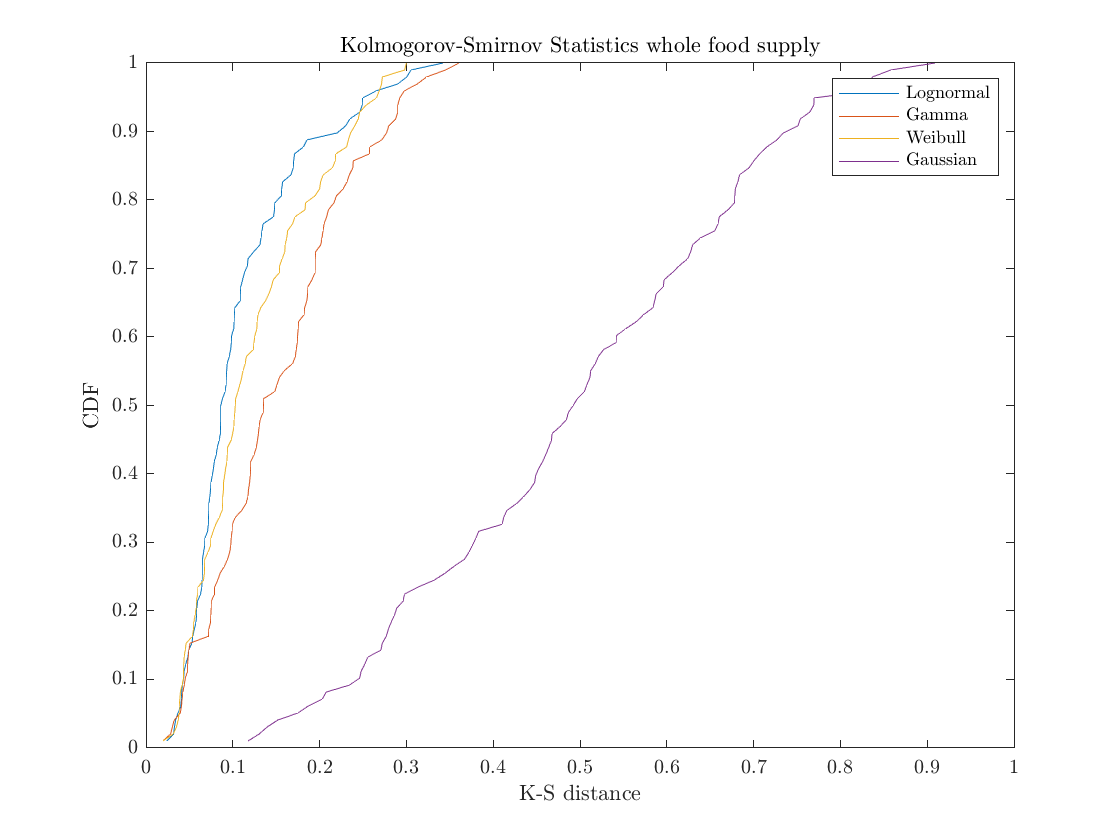

label="Water";
nuttablestat(strcmpi(label, nuttablestat.Nutrient_description),:) = [];
figure,
[y,x]=ecdf(nuttablestat.ksstatL(~isnan(nuttablestat.ksstatL)));
plot(x(2:end), y(2:end))
hold on
[y,x]=ecdf(nuttablestat.ksstatG(~isnan(nuttablestat.ksstatG)));
plot(x(2:end), y(2:end))
hold on
[y,x]=ecdf(nuttablestat.ksstatW(~isnan(nuttablestat.ksstatW)));
plot(x(2:end), y(2:end))
hold on
[y,x]=ecdf(nuttablestat.ksstatN(~isnan(nuttablestat.ksstatN)));
plot(x(2:end), y(2:end))
xlabel("K-S distance")
ylabel("CDF")
legend({"Lognormal", "Gamma","Weibull" "Gaussian"})
title("Kolmogorov-Smirnov Statistics whole food supply") 

Logarithmic Skewness

tlog=script_SK_nutrients(nutlist, fooddatabase0910selclean, muf,sf);

     5

Truncated Lognormal
No convergence


    15

Truncated Gaussian
No convergence
Fit Half Gaussian


    18

Truncated Gaussian
No convergence
Fit Half Gaussian


    37

Truncated Gaussian
No convergence
Fit Half Gaussian


    52

Truncated Gaussian
No convergence
Fit Half Gaussian
    55

Truncated Gaussian
No convergence
Fit Half Gaussian


    98

Truncated Gaussian
No convergence
Fit Half Gaussian


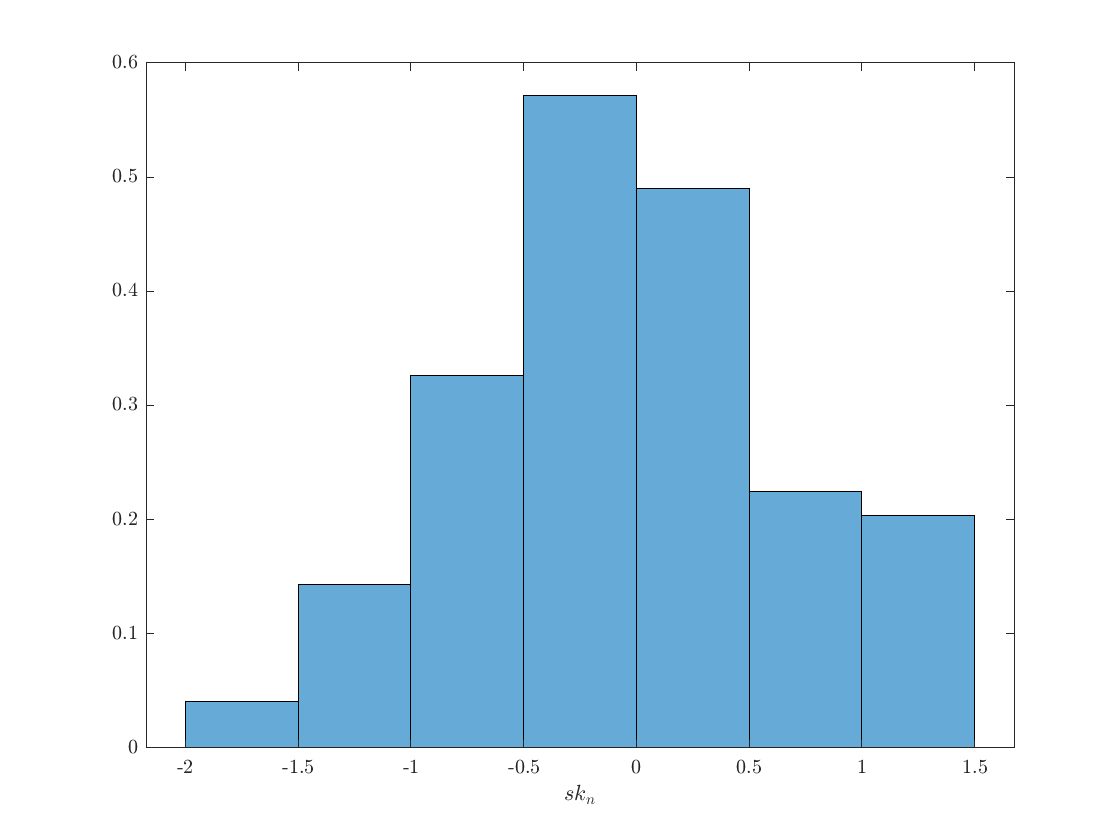

tlog.ischem=tfndds.ischem;
label="Water";
tlog(strcmpi(label, tlog.Nutrient_description),:) = [];

figure,
histogram(tlog.sk, 'Normalization', 'PDF')
xlabel("$sk_n$",'Interpreter', 'Latex')

Logarithmic Standard Deviation

tlogSD=script_SD_nutrients(nutlist, fooddatabase0910selclean, muf,sf);

     5

Truncated Lognormal
No convergence


    15

Truncated Gaussian
No convergence
Fit Half Gaussian


    18

Truncated Gaussian
No convergence
Fit Half Gaussian


    37

Truncated Gaussian
No convergence
Fit Half Gaussian


    52

Truncated Gaussian
No convergence
Fit Half Gaussian
    55

Truncated Gaussian
No convergence
Fit Half Gaussian


    98

Truncated Gaussian
No convergence
Fit Half Gaussian


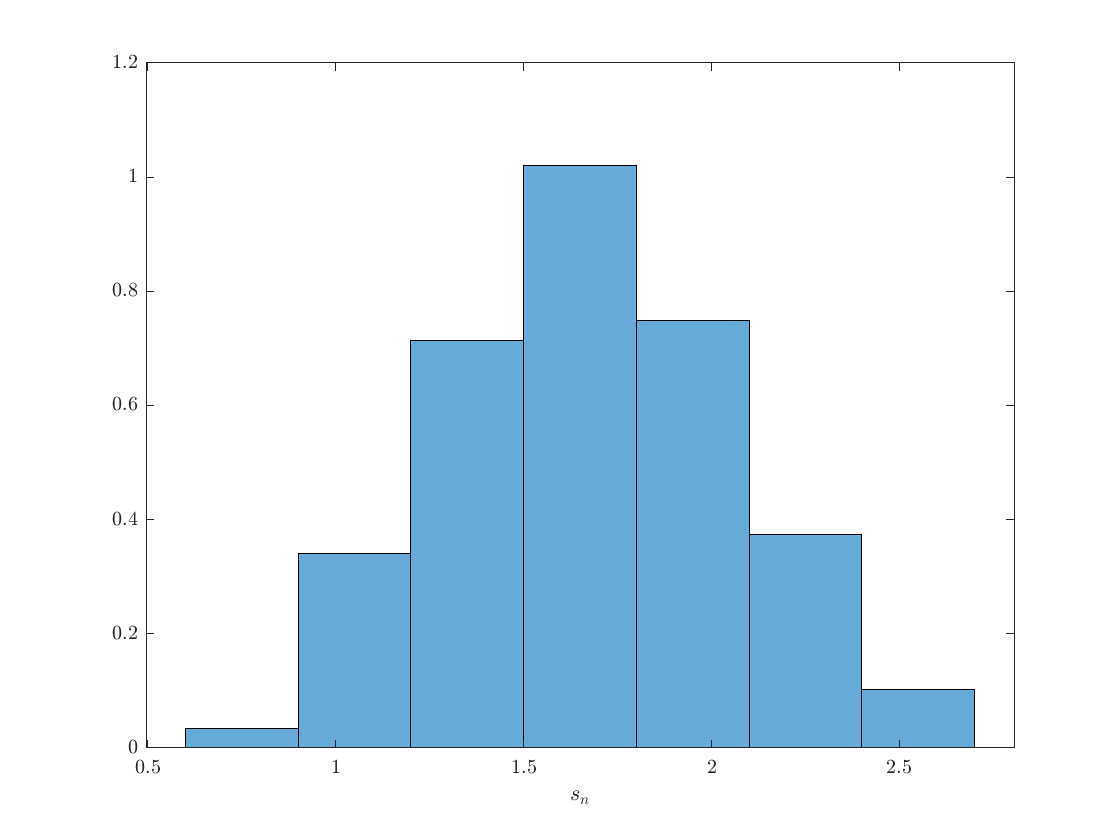

tlogSD.ischem=tfndds.ischem;
label="Water";
tlogSD(strcmpi(label, tlogSD.Nutrient_description),:) = [];

figure,
histogram(tlogSD.sd, 'Normalization', 'PDF')
xlabel("$s_n$",'Interpreter', 'Latex')

Summary Figure

labels={"Vitamin B-12", "Thiamin", "Zinc", "20:1","Protein"};
labels2={"Vitamin B-12", "Thiamin", "Zinc", "Gadoleic Acid","Protein"};

cmap = cbrewer('div','Spectral',length(muf));

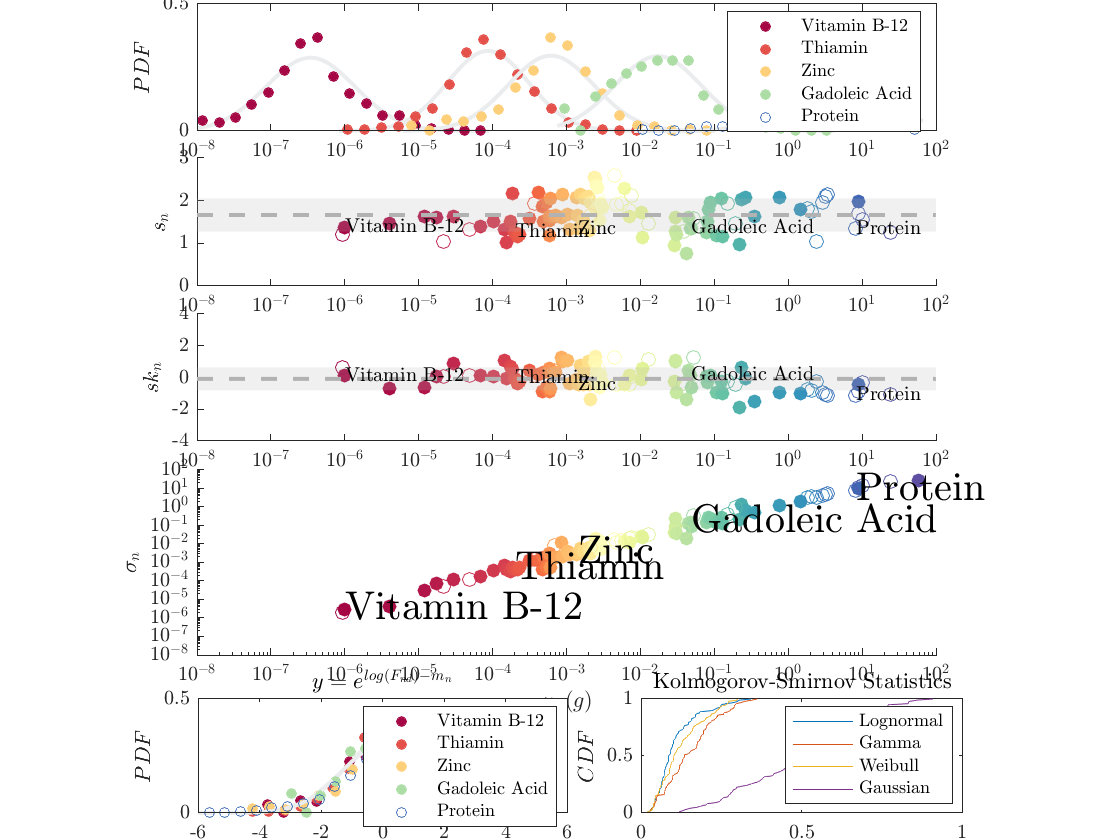

[mufs, inds]=sort(muf);
sfs=sf(inds);
ischem=tfndds.ischem(inds);
lbs=tfndds.Nutrient_description(inds);
nind=zeros(length(labels),1);

for ind=1:length(labels)
nind(ind)=find(strcmpi(labels{ind}, lbs));
end
colorsel=cmap(nind,:);

Nb=18;
figure(1)
C = {{[]};{[]};{[]};{[]};{{[]}, {[]}}};
[ha,labelfontsize] = subplotplus(C);

subidx = 1;
set(gcf,'CurrentAxes',ha(subidx));
xl=[10^(-8), 10^(-7),10^(-6),10^(-5),10^(-4), 10^(-3),10^(-2),10^(-1), 10^0 , 10^1, 10^2];
lxl=log(xl);

for ind=1:length(labels)
    filternut=strcmpi(labels{ind}, nutlist.Nutrient_description);
    v=fooddatabase0910selclean(filternut,:);
    v=v(v>0);
    h=histogram(log(v),Nb, 'normalization', 'pdf', 'EdgeAlpha', 1, 'FaceAlpha', 0.3 );
    hold on
    centers=h.BinEdges+h.BinWidth/2;
    centers=centers(1:end-1);
    pdfvalues=h.Values;

    hold on
    [p1,p2]=normfit(log(v));
    x=linspace(min(h.BinEdges), max(h.BinEdges),1000);
    y=normpdf(x, p1,p2);
    plot(x,y, 'color', [234, 236, 238]/255,'HandleVisibility','off', 'LineWidth',2)
    hold on
    delete(h)
    hold on

    if nuttablestat.ischem(filternut)
      plot(centers, pdfvalues,'x', 'Color', colorsel(ind,:),'marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5, 'MarkerFaceColor' ,  colorsel(ind,:))  
    else
      plot(centers, pdfvalues,'x', 'Color', colorsel(ind,:),'marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5)  
    end
end

xlabel('$x(g)$','interpreter','latex')
ylabel('$PDF$','interpreter','latex')
legend(labels2)

xticks(lxl)
xticklabels({'$10^{-8}$', '$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;
c = ax.Color;
ax.TickLabelInterpreter  = 'latex';
axis([lxl(1) lxl(end) 0 0.5])



subidx = 2;
set(gcf,'CurrentAxes',ha(subidx));

cmapnew=cmap(1:end-1,:);
xl=[10^(-8), 10^(-7),10^(-6),10^(-5),10^(-4), 10^(-3),10^(-2),10^(-1), 10^0 , 10^1, 10^2];
lxl=log(xl);
tlogSD1 = sortrows(tlogSD,'muf','ascend');
scatter(log(tlogSD1.muf(tlogSD1.ischem)),tlogSD1.sd(tlogSD1.ischem),50,cmapnew(tlogSD1.ischem,:),'filled')
hold on
scatter(log(tlogSD1.muf(~tlogSD1.ischem)),tlogSD1.sd(~tlogSD1.ischem),50,cmapnew(~tlogSD1.ischem,:))

xlabel('$\mu_n(g)$','Interpreter', 'Latex')
ylabel('$s_n$','Interpreter', 'Latex')
 
 
hold on
 
x=lxl(1):0.001:lxl(end);
Xconf=[x x(end:-1:1)];
ssk=std(tlogSD.sd);
msk=mean(tlogSD.sd)*ones(1,length(x));
mskl=msk-ssk;
msku=msk+ssk;
Yconf=[msku, mskl(end:-1:1)];
 
p = fill(Xconf,Yconf,[178 178 178]/255,'HandleVisibility','off');
p.FaceAlpha=0.2;     
p.EdgeColor = 'none';     
hold on
plot(x, msk, '--', 'LineWidth', 2, 'Color', [178 178 178]/255)

hold on

x=zeros(length(labels),1);
y=zeros(length(labels),1);
for ind=1:length(labels)
   filternut=strcmpi(labels{ind}, tlogSD1.Nutrient_description);
   x(ind)=log(tlogSD1.muf(filternut));
   y(ind)=tlogSD1.sd(filternut);
end

for ind=1:length(labels2)
    text(x(ind),y(ind),labels2{ind}, 'FontSize',10,'FontWeight', 'bold')
end

 
xticks(lxl)
xticklabels({'$10^{-8}$','$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;
ax.TickLabelInterpreter  = 'latex';
axis([lxl(1) lxl(end) 0 3])


subidx = 3;
set(gcf,'CurrentAxes',ha(subidx));

cmapnew=cmap(1:end-1,:);
tlog1 = sortrows(tlog,'muf','ascend');
scatter(log(tlog1.muf(tlog1.ischem)),tlog1.sk(tlog1.ischem),50,cmapnew(tlog1.ischem,:),'filled')
hold on
scatter(log(tlog1.muf(~tlog1.ischem)),tlog1.sk(~tlog1.ischem),50,cmapnew(~tlog1.ischem,:))

xlabel('$\mu_n(g)$','Interpreter', 'Latex')
ylabel('$sk_n$','Interpreter', 'Latex')
 
 
hold on
 
x=lxl(1):0.001:lxl(end);
Xconf=[x x(end:-1:1)];
ssk=std(tlog.sk);
msk=mean(tlog.sk)*ones(1,length(x));
mskl=msk-ssk;
msku=msk+ssk;
Yconf=[msku, mskl(end:-1:1)];
 
p = fill(Xconf,Yconf,[178 178 178]/255,'HandleVisibility','off');
p.FaceAlpha=0.2;     
p.EdgeColor = 'none';     
hold on
plot(x, msk, '--', 'LineWidth', 2, 'Color', [178 178 178]/255)

  
hold on


x=zeros(length(labels),1);
y=zeros(length(labels),1);
for ind=1:length(labels)
filternut=strcmpi(labels{ind}, tlog1.Nutrient_description);

x(ind)=log(tlog1.muf(filternut));
y(ind)=tlog1.sk(filternut);

end

for ind=1:length(labels2)
    text(x(ind),y(ind),labels2{ind}, 'FontSize',10,'FontWeight', 'bold')
end
 
hold on
 
xticks(lxl)
xticklabels({'$10^{-8}$','$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;

ax.TickLabelInterpreter  = 'latex';
axis([lxl(1) lxl(end) -4 4])



subidx = 4;
set(gcf,'CurrentAxes',ha(subidx));
muf=zeros(size(fooddatabase0910selclean,1),1);
sf=zeros(size(fooddatabase0910selclean,1),1);


for ind=1:size(fooddatabase0910selclean,1)
    v=fooddatabase0910selclean(ind,:);
    muf(ind)=mean(v(v>0));
    sf(ind)=std(v(v>0));
end

cvreal=sf./muf;



mv=zeros(length(labels),1);
sv=zeros(length(labels),1);
for ind=1:length(labels)
filternut=strcmpi(labels{ind}, nutlist.Nutrient_description);
v=fooddatabase0910selclean(filternut,:);
v=v(v>0);
mv(ind)=mean(v);
sv(ind)=std(v);

end

[~, inds]=sort(mv);
labels=labels(inds);
labels2=labels2(inds);
mv=mv(inds);
sv=sv(inds);

    
scatter(mufs(ischem),sfs(ischem),50,cmap(ischem,:),'filled')
hold on
scatter(mufs(~ischem),sfs(~ischem),50,cmap(~ischem,:))

set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')
xlabel('$\mu_n(g)$','Interpreter', 'Latex')
ylabel('$\sigma_n$','Interpreter', 'Latex')

hold on

for ind=1:length(labels2)
    text(mv(ind),sv(ind),labels2{ind}, 'FontSize',20,'FontWeight', 'bold')
end



xl=[10^(-8), 10^(-7),10^(-6),10^(-5),10^(-4), 10^(-3),10^(-2),10^(-1), 10^0 , 10^1, 10^2];
xticks(xl)
xticklabels({'$10^{-8}$', '$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;
ax.TickLabelInterpreter  = 'latex';

yticks(xl)
yticklabels({'$10^{-8}$', '$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;
ax.TickLabelInterpreter  = 'latex';
colorsel=cmap(nind,:);
axis([xl(1) xl(end) xl(1) xl(end)])


subidx = 5;
set(gcf,'CurrentAxes',ha(subidx));

mext=zeros(length(labels),1);
sext=zeros(length(labels),1);
for ind=1:length(labels)
filternut=strcmpi(labels{ind}, nutlist.Nutrient_description);
v=fooddatabase0910selclean(filternut,:);
v=v(v>0);
mext(ind)=nutlist.muL(filternut);
sext(ind)=nutlist.sigmaL(filternut);

vt=exp((log(v)-mext(ind)));
h=histogram(log(vt), Nb, 'normalization', 'pdf', 'EdgeAlpha', 1, 'FaceAlpha', 0.3);hold on
centers=h.BinEdges+h.BinWidth/2;
centers=centers(1:end-1);
pdfvalues=h.Values;

hold on
[p1,p2]=normfit(log(vt));
x=linspace(min(h.BinEdges), max(h.BinEdges),1000);
y=normpdf(x, p1,p2);
plot(x,y,'--', 'color', [234, 236, 238]/255,'HandleVisibility','off', 'LineWidth',2)
hold on
delete(h)
hold on

if nuttablestat.ischem(filternut)

plot(centers, pdfvalues,'x', 'Color', colorsel(ind,:),'marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5, 'MarkerFaceColor' ,  colorsel(ind,:))  
else
plot(centers, pdfvalues,'x', 'Color', colorsel(ind,:),'marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5)  
    
end

end
legend(labels2)
xlabel('$log(y)$','interpreter','latex')
title('$y=e^{log(F_{nd})-m_n}$','interpreter','latex')
ylabel('$PDF$','interpreter','latex')

ax = gca;
ax.TickLabelInterpreter  = 'latex';
axis([-6 6 0 0.5])



subidx = 6;
set(gcf,'CurrentAxes',ha(subidx));
label="Water";
nuttablestat2=nuttablestat;
nuttablestat2(strcmpi(label, nuttablestat.Nutrient_description),:) = [];


[y,x]=ecdf(nuttablestat2.ksstatL(~isnan(nuttablestat2.ksstatL)));
plot(x(2:end), y(2:end))
hold on
[y,x]=ecdf(nuttablestat2.ksstatG(~isnan(nuttablestat2.ksstatG)));
plot(x(2:end), y(2:end))
hold on
[y,x]=ecdf(nuttablestat2.ksstatW(~isnan(nuttablestat2.ksstatW)));
plot(x(2:end), y(2:end))
hold on
[y,x]=ecdf(nuttablestat2.ksstatN(~isnan(nuttablestat2.ksstatN)));
plot(x(2:end), y(2:end))
xlabel("$KS \ distance$",'Interpreter', 'Latex')
ylabel("$CDF$",'Interpreter', 'Latex')
legend({"Lognormal", "Gamma","Weibull" "Gaussian"})
title("Kolmogorov-Smirnov Statistics")
ax = gca;
ax.TickLabelInterpreter  = 'latex';


ha(1).Position=[0.176328502415459 0.844187963726298 0.659717210736468 0.151483177213298];
ha(2).Position=[0.176328502415459 0.66 0.659359 0.151483177213298];
ha(3).Position=[0.176328502415459 0.475 0.659359 0.151483177213298];
ha(4).Position=[0.176328502415459 0.22 0.659174964852608 0.22];
ha(5).Position=[0.176686713151927 0.0318 0.3296795 0.13648];
ha(6).Position=[0.572 0.0318 0.286734693877551 0.13648];